# Algoritmo enjambre de particulas - El problema del despacho economico de energía en un sistema IEEE 30-bus de generadores termo-electricos

## Definición de parametros:

- a es el costo cuadratico, representa que el costo por MW no es constante, sino que aumenta a medida que el generador se acerca a su capacidad maxima.

- b es el costo marginal, representa de forma lineal cuanto cuesta cada MW adicional generado sin tener en cuenta las perdidas.

- c es el costo de mantener el generador encendido aunque no este generando.

- Bij, Boj, Boo son las matrices de Kronn y representan las perdidas electricas:

- Bij representa la ubicación eléctrica de cada generador respecto a la carga y entre generadores, depende de las impedancias de linea (I^2R).

- Boj representa las perdidas fijas de cada generador.

- Boo representa las perdidas fijas de la red.

- Es necesario colocar restricciones de potencia maxima y minima de cada generador y sobretodo una condición que obligue a la población a cumplir 

## Parametros:

clear; clc;

a = [0.00375, 0.0175, 0.0625, 0.00834, 0.025, 0.025];
b = [2.00, 1.75, 1, 3.25, 3, 3];
c = [0, 0, 0, 0, 0, 0];

Pmin = [50, 20, 15, 10, 10, 12]; %Potencia minima de cada generador
Pmax = [200, 80, 50, 35, 30, 40]; %Potencia maxima de cada generador

%Matriz B simetrica fija
B = [
    0.000218   0.000103   0.000009  -0.00010   0.000002   0.000027;
    0.000103   0.000181   0.000004  -0.000015  0.000002   0.000030;
    0.000009   0.000004   0.000417  -0.000131 -0.000153  -0.000107;
    -0.00010   -0.000015  -0.000131   0.000221  0.000094   0.000050;
    0.000002   0.000002  -0.000153   0.000094  0.000243  -0.00000;
    0.000027   0.000030  -0.000107   0.000050 -0.00000   0.000358
    ];

%Matriz B fila
B0 = [-0.000003  0.000021  -0.000056  0.000034  0.000015  0.000078];

%Matriz B escalar
B00 = 0.000014;

Peso = 1e4; %Obliga al algoritmo a respetar el balance de potencia
Pdemanda = 283.4; %MW

## Random

%n = numel(a);

%B simétrica
%rango_B = [-0.0002, 0.0005];
%B_random = rango_B(1) + (rango_B(2)-rango_B(1)) * rand(n, n);
%B = (B_random + B_random') / 2;

%B0 fila
%rango_B0 = [-0.0001, 0.0001];
%B0 = rango_B0(1) + (rango_B0(2)-rango_B0(1)) * rand(1, n);

%B00 escalar
%rango_B00 = [0, 0.00005];
%B00 = rango_B00(1) + (rango_B00(2)-rango_B00(1)) * rand();

## Función de costo


                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              50            3077       1.762e+07        0
    1             100            3077       4.511e+07        0
    2             150            3077       1.769e+07        1
    3             200            3077        2.64e+07        2
    4             250            3077       2.219e+07        3
    5             300            3077       2.443e+07        4
    6             350            3077       1.987e+07        5
    7             400            1776       1.343e+07        0
    8             450            1776       8.302e+06        1
    9             500            1215       7.092e+06        0
   10             550            1215       4.695e+06        1
   11             600            1126       3.983e+06        0
   12             650            1126       3.319e+06        1
   13             700           892.3        2.3

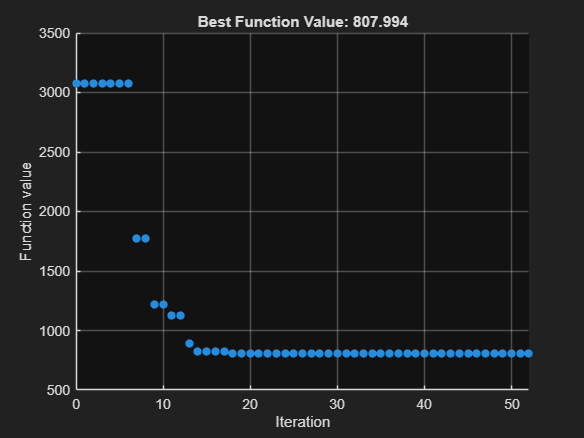

P_opt =   150.9013   50.5417   21.7446   26.4296   14.5854   26.1522


F_opt = 807.9936

exitflag = 1

output = struct with fields:
      rngstate: [1×1 struct]
    iterations: 52
     funccount: 2650
       message: 'Optimization ended: relative change in the objective value ↵over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.'
    hybridflag: []


function PL = perdidasTransmision(P, B, B0, B00)
PL = P * B * P' + B0 * P' + B00;
end

function F = funcionCosto(P, a, b, c, Pdemanda, B, B0, B00, Peso)
%Costo base de generación
costo = sum(a .* P.^2 + b .* P + c);

%Pérdidas de transmisión
PL = perdidasTransmision(P, B, B0, B00);

%Penalización por no cumplir el balance de potencia
desbalance = sum(P) - Pdemanda - PL;

penalizacion = Peso * desbalance^2;

F = costo + penalizacion;
end

%Llamado de la función de costo
fun = @(P) funcionCosto(P, a, b, c, Pdemanda, B, B0, B00, Peso);

## Algoritmo

Options = optimoptions('particleswarm', ...
    'SwarmSize', 50, ... %Cantidad de particulas
    'MaxIterations', 200, ... %Maximo de iteraciones
    'FunctionTolerance', 1e-9, ... 
    'Display', 'iter', ...
    'PlotFcn', 'pswplotbestf');


%fun = @(P) funcionObjetivoConPerdidas(P, a, b, c, Pdemanda, B, B0, B00);

[P_opt, F_opt, exitflag, output] = particleswarm(fun, numel(a), Pmin, Pmax, Options)
